# Interpolation in MATLAB

## 8.1 Interpolation in one dimension

clear all; %clear MATLAB's memory
close all; %close all figures

format short %use this to avoid losing precision
T = readtable('L8_bedf.csv');
x = table2array(T(:,1))

x =     0.3340
    2.6910
    7.9480
   10.4860
   11.7550
   15.0180
   14.6550
   15.9240
   16.1060
   18.6440


y = table2array(T(:,2))

y =    70.8120
   62.1140
   50.5180
   45.4440
   50.5180
   59.2150
   59.7590
   61.5710
   62.6580
   68.2750


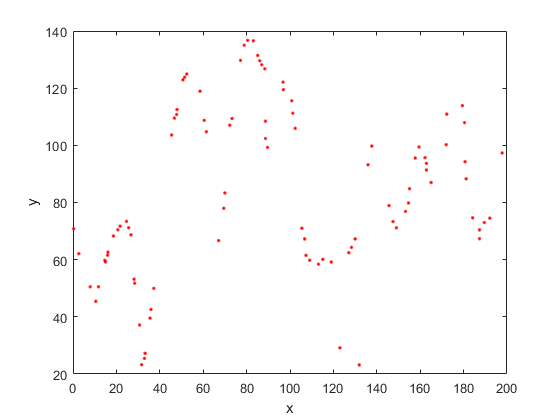

plot(x,y,'.r') %plot the data as red points
xlabel('x'), ylabel('y') %label the axes


%Remove duplicatees
[x, index] = unique(x);
y = y(index);


## 8.1.1 Piecewise Linear Interpolation

y0 = interp1(x,y,100,'linear')

y0 = 116.4356

%%using the (x,y) data make a linear estimate of y at x=41

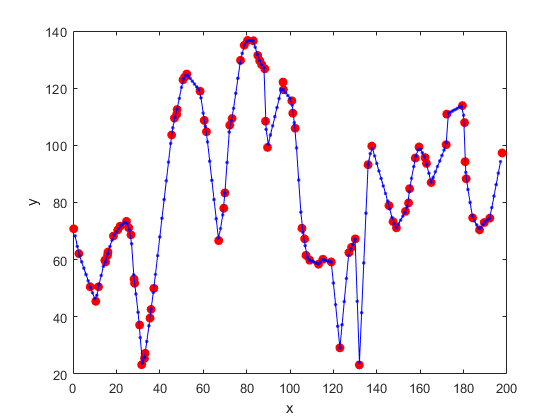

figure %produce a new figure
plot(x,y,'or','markerfacecolor','r') %plot the original data
hold on
x0=[0:1:200]'; %generate the equally spaced x array
y0=interp1(x,y,x0,'linear'); %interpolate y onto x0
plot(x0,y0,'.b-')%plot the linear interpolation
xlabel('x'), ylabel('y') %label the axes

[x0(1:3),y0(1:3)] %list the first 3 values of the interpolated data

ans =          0       NaN
    1.0000   68.3543
    2.0000   64.6640


x(1:3) %the first value of the x input data

ans =     0.3340
    2.6910
    7.9480


%consider extrapolation as well
y0=interp1(x,y,x0,'linear','extrap'); %add a 5th option to perform extrapolation
[x0(1:3),y0(1:3)] %we now have predicted y-values outside of the measured x-range

ans =          0   72.0446
    1.0000   68.3543
    2.0000   64.6640


## 8.1.2 Nearest neighbor interpolation

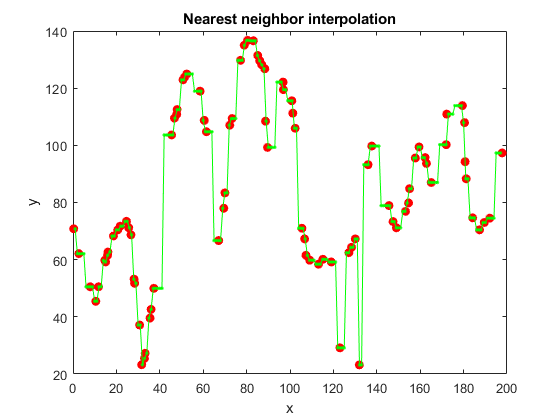

y0=interp1(x,y,x0,'nearest'); %interpolate y onto x0 using the nn approach
figure %produce a new figure
plot(x,y,'or','markerfacecolor','r') %plot the original data
xlabel('x'), ylabel('y') %label the axes
hold on
plot(x0,y0,'.g-') %plot the nearest-neighbor interpolation
title('Nearest neighbor interpolation')

%from ungridded to gridded data after interpolation

## 8.1.3 Cubic Spline Interpolation

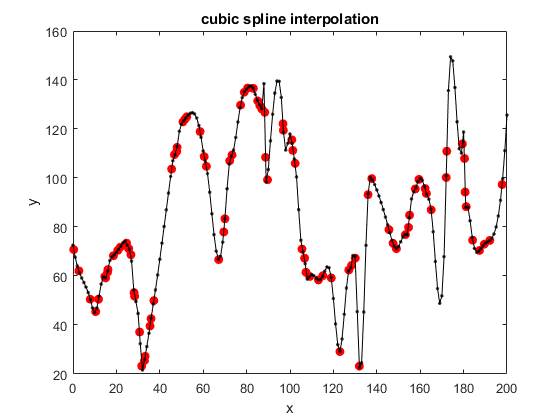

y0=interp1(x,y,x0,'spline'); %interpolate y onto x0 using a cubic spline
figure %produce a new figure
plot(x,y,'or','markerfacecolor','r') %plot the original data
xlabel('x'), ylabel('y') %label the axes
hold on
plot(x0,y0,'.k-') %plot the cubic spline interpolation
title('cubic spline interpolation')

## 8.1.4 PCHIP Interpolation - inbetween linear and spline

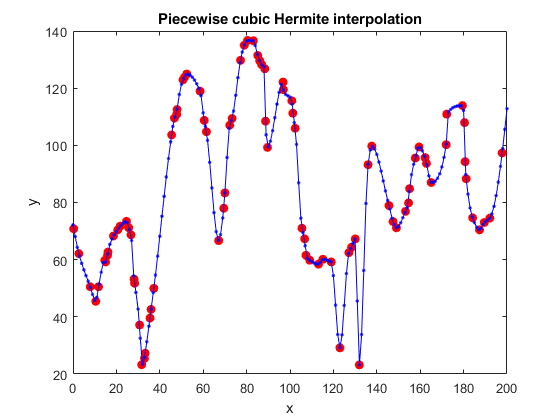

y0=interp1(x,y,x0,'pchip'); %interpolate y onto x0 using pchip
figure %produce a new figure
plot(x,y,'or','markerfacecolor','r') %plot the original data
xlabel('x'), ylabel('y') %label the axes
hold on
plot(x0,y0,'.b-') %plot the pchip interpolation
title('Piecewise cubic Hermite interpolation')

## 8.2 The danger of extrapolation

close all
x=[0:1:96] % selection of x data sites

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


y=sin(2.*pi.*x./25) %sine function with a period of 25 units

y =          0    0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980   -0.9511   -0.8443   -0.6845   -0.4818   -0.2487   -0.0000    0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980   -0.9511   -0.8443   -0.6845   -0.4818   -0.2487


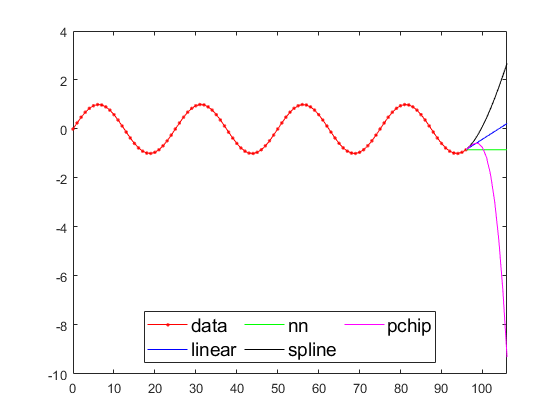

plot(x,y,'.r-') %plot the data
set(gca,'xlim',[0 106]) %extend the graphic window
x0=[96:1:110]; %x locations for extrapolation
y0=interp1(x,y,x0,'linear','extrap'); %linear extrapolation
hold on
plot(x0,y0,'b') %add linear extrapolation to the figure
y0=interp1(x,y,x0,'nn','extrap'); %nn extrapolation
plot(x0,y0,'g') %add nn extrapolation to the figure
y0=interp1(x,y,x0,'spline','extrap'); %cubic spline extrapolation
plot(x0,y0,'k') %add spline extrapolation to the figure
y0=interp1(x,y,x0,'pchip','extrap'); %pchip extrapolation
plot(x0,y0,'m') %add pchip extrapolation to the figure
legend({'data','linear','nn','spline','pchip'},'Location','south','NumColumns',3,'FontSize',14) %add a legend

help legend

  legend Create legend
  
  legend creates a legend with descriptive labels for each plotted data
  series. For the labels, the legend uses the text from the DisplayName
  properties of the data series. If the DisplayName property is empty, then
  the legend uses a label of the form 'dataN'. The legend automatically
  updates when you add or delete data series from the axes. This command
  creates a legend for the current axes or chart returned by gca. If the
  current axes is empty, then the legend is empty. If axes do not exist,
  then this command creates one.
 
  legend(label1,...,labelN) sets the labels. Specify the labels as a
  list of character vectors, such as legend('Jan','Feb','Mar').
 
  legend(labels) sets the labels using a cell array of character vectors or
  a character matrix, such as legend({'Jan','Feb','Mar'}).
 
  legend(subset,__) only includes items in the legend for the data seri

## 8.3 Interpolation in two dimensions

load topo %data containing the variables x, y, z
figure %create a new figure window
z = -25 + rand(1,97)*(20+25)

z =    17.7993  -19.0157  -21.8362    6.7737   16.9266  -20.0995    4.3264  -18.4272    6.2283    3.1526  -23.0324   10.9066   19.3795   -5.3465   -9.4863  -22.8037  -14.8659    1.1456    2.0619  -13.6367    4.4454  -22.2957   17.3228  -20.8361   -9.9710    4.2972   -2.3240   -1.1084   -7.9394    9.6008  -12.2870    4.2173   16.4983  -10.1198   11.6048   10.4436  -19.4055  -17.9176   -6.3251    5.9300    4.5967    5.5990  -24.5776  -19.2126    9.3758   12.8862    8.6127   17.5036   16.3871  -14.9617


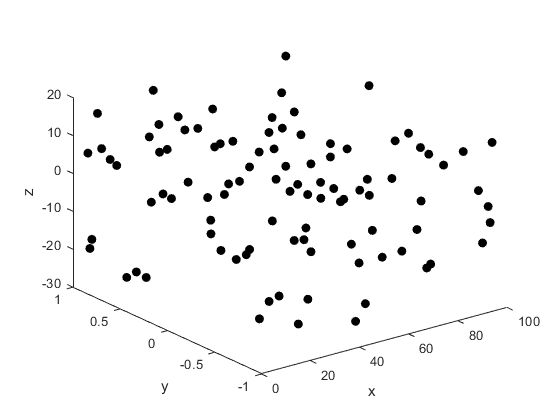

plot3(x,y,z,'ok','markerfacecolor','k') %plot the data as black points
xlabel('x'), ylabel('y'), zlabel('z') %label the axes

x0=[420:0.25:470]; %define x-locations for grid (201 points)
y0=[70:0.25:120]; %define y-locations for grid (201 points)
[XI,YI]=meshgrid(x0,y0); %generate x,y grids (201 x 201 points)
%create a regular grid for interpolation
ZI=griddata(x,y,z,XI,YI,'linear'); %perform the linear interpolation
hold on
surf(XI,YI,ZI) %plot the interpolated surface

% shading interp, light %smooth the surface appearance and illuminate